% 清空工作空間
clear;
clc;

% 設置隨機數種子，確保結果一致
rng(42);

% 設定參數的統計特性（根據表格）
param_stats = struct( ...
    'Range',      [250, 0.2, 120, 350, 120, 5.4, 0.02; ... % 最小值
                   450, 0.3, 270, 525, 300, 193.5, 0.71; ... % 平均值
                   700, 0.5, 390, 700, 480, 382, 1.4], ... % 最大值
    'StdError',   [11.909, 0.010, 11.773, 10.781, 9.861, 9.702, 0.033], ...
    'StdDev',     [98.206, 0.083, 97.083, 88.901, 81.315, 80.004, 0.269], ...
    'Variance',   [9644.425, 0.007, 9425.176, 7903.314, 6612.116, 6400.660, 0.072]);

% 生成數據樣本數量
num_samples = 500; % 樣本數量

% 預設參數數量（7 個參數）
num_params = size(param_stats.Range, 2);

% 初始化數據矩陣
data = zeros(num_samples, num_params);

% 根據範圍、標準差和變異數生成隨機數據
for i = 1:num_params
    % 提取參數統計特性
    min_val = param_stats.Range(1, i);
    max_val = param_stats.Range(3, i);
    std_dev = param_stats.StdDev(i);
    
    % 正態分布生成數據，並調整到範圍內
    data(:, i) = normrnd(param_stats.Range(2, i), std_dev, [num_samples, 1]); % 使用正態分布
    data(:, i) = max(min(data(:, i), max_val), min_val); % 修到範圍內
end

% 分配生成數據到對應變數
ReactionTemp = data(:, 1);      % 反應溫度 (°C)
CatalystWeight = data(:, 2);    % 催化劑重量 (g)
TimeOnStream = data(:, 3);      % 反應時間 (min)
CalcinationTemp = data(:, 4);   % 焙燒溫度 (°C)
CalcinationTime = data(:, 5);   % 焙燒時間 (min)
SurfaceArea = data(:, 6);       % 比表面積 (m²/g)
PoreVolume = data(:, 7);        % 孔體積 (cm³/g)

% 假設的氫氣產率（加入noise）
HydrogenYield = 12 + (84 - 12) * rand(num_samples, 1) + normrnd(0, 13.889, [num_samples, 1]); % 平均值 13.889

% 整合輸入和輸出
inputs = [ReactionTemp, CatalystWeight, TimeOnStream, CalcinationTemp, ...
          CalcinationTime, SurfaceArea, PoreVolume]';  % 7 個參數輸入
targets = HydrogenYield';                              % 氫氣產率作為目標

## 自動化神經網路訓練

hiddenLayerSize = 19; % 設置隱藏層神經元數量
net = fitnet(hiddenLayerSize);

% 將數據分割為訓練、驗證和測試集
[net, tr] = train(net, inputs, targets);

% 測試神經網路
outputs = net(inputs);
performance = perform(net, targets, outputs);

% 顯示訓練結果
disp(['訓練完成，性能指標（MSE）：', num2str(performance)]);

訓練完成，性能指標（MSE）：567.1868


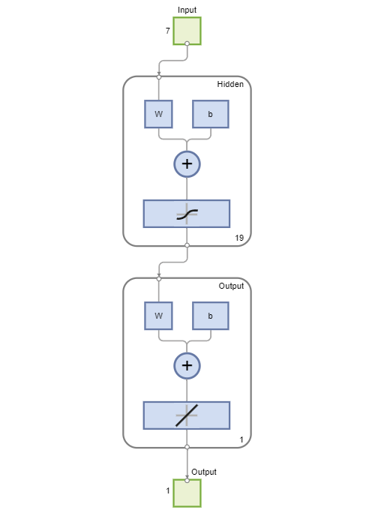

view(net); % 可視化網路結構

## 使用 GA 進行優化

% 定義適應度函數，負號是為了最大化氫氣產率
fitnessFunction = @(input) -net(input');

% 定義變數上下界（輸入參數範圍）
lb = param_stats.Range(1, :); % 各參數下界
ub = param_stats.Range(3, :); % 各參數上界

% 設定遺傳算法選項
options = optimoptions('ga', ...
    'Display', 'iter', ...
    'PopulationSize', 100, ...
    'MaxGenerations', 100, ...
    'UseParallel', false);

% 執行遺傳算法
[optimalInput_GA, optimalOutput_GA] = ga(fitnessFunction, 7, [], [], [], [], lb, ub, [], options);


Single objective optimization:
7 Variables

Options:
CreationFcn:       @gacreationuniform
CrossoverFcn:      @crossoverscattered
SelectionFcn:      @selectionstochunif
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              200          -61.27          -47.33        0
    2              295          -61.27           -48.9        1
    3              390          -63.82          -50.48        0
    4              485          -63.82          -52.16        1
    5              580          -63.82          -53.96        2
    6              675          -64.94          -55.47        0
    7              770          -64.94          -58.22        0
    8              865          -64.94          -58.28        1
    9              960          -64.94          -58.91        2
   10             1055          -64.94          -60.17        3
   11        


% 反轉符號以獲得實際的最大化結果
optimalOutput_GA = -optimalOutput_GA;

% 顯示最佳解
fprintf('最佳輸入（GA）：\n');

最佳輸入（GA）：


disp(array2table(optimalInput_GA, 'VariableNames', ...
    {'ReactionTemp', 'CatalystWeight', 'TimeOnStream', ...
     'CalcinationTemp', 'CalcinationTime', 'SurfaceArea', 'PoreVolume'}));

    ReactionTemp    CatalystWeight    TimeOnStream    CalcinationTemp    CalcinationTime    SurfaceArea    PoreVolume
    ____________    ______________    ____________    _______________    _______________    ___________    __________

       490.99          0.48599           294.53           614.83             474.27            373.5         1.3529  



fprintf('最佳輸出（氫氣產率, GA）：%.4f%%\n', optimalOutput_GA);

最佳輸出（氫氣產率, GA）：64.9408%


## 繪製結果

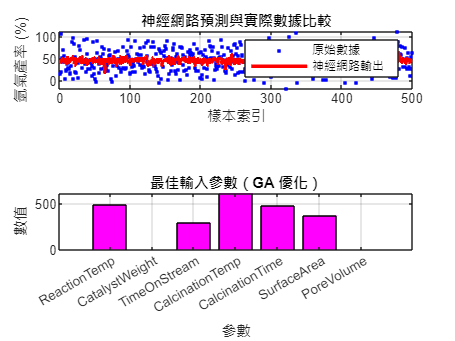

figure;
subplot(2, 1, 1);
plot(1:num_samples, targets, 'b.', 'DisplayName', '原始數據');
hold on;
plot(1:num_samples, outputs, 'r-', 'LineWidth', 2, 'DisplayName', '神經網路輸出');
title('神經網路預測與實際數據比較');
xlabel('樣本索引');
ylabel('氫氣產率 (%)');
legend;
grid on;

subplot(2, 1, 2);
bar(optimalInput_GA, 'FaceColor', 'm');
xticklabels({'ReactionTemp', 'CatalystWeight', 'TimeOnStream', ...
             'CalcinationTemp', 'CalcinationTime', 'SurfaceArea', 'PoreVolume'});
title('最佳輸入參數（GA 優化）');
xlabel('參數');
ylabel('數值');
grid on;